clear;

(a) (7 points) Consider an ellipse, within a 2D Euclidean plane, with center at the origin, and with major and minor axes of lengths 2 and 1 along the cardinal axes. Propose an implementable algorithm for generating random points (in 2D) distributed uniformly inside the ellipse. 

go to circle first

X ~ uniform(0,1) ~ Y

justify the following using multivariate transformation 

r = R sqrt(X)

theta = 2pi Y

(rcostheta, rsintheta)

circle - > ellipse, stretch x axis by 2

(2rcostheta, rsintheta)

(b) (5 points) Implement the algorithm described in the previous sub-question. Use it to sample N = 107 independent points (in 2D) and plot a 2D histogram of the sample. You may use the Matlab function histogram2(), e.g., with ’DisplayStyle’ as ’tile’. 

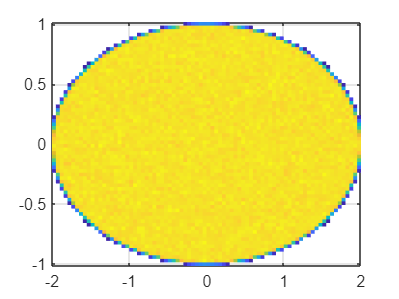

N = 10^7;
r = sqrt(rand(N,1));
theta = 2*pi*rand(N,1);

X= 2*r.*cos(theta);
Y = r.*sin(theta);

histogram2(X,Y,DisplayStyle="tile");

(c) (8 points) Consider a triangle in a 2D Euclidean plane with vertices at (0, 0), (π, 0), (π/3, exp(1)). Propose an implementable algorithm for generating random points (in 2D) distributed uniformly inside the triangle. 

consider the triangle with vertices (0,0), (0,1),(1,1);

our triangle is this triangle transformed by [pi,-2pi/3; 0,e]

we generate draws for the first triangle easily using its symmetry, as (max(X1,X2),min(X1,X2)) (justify dear jv)

X1 ~ uniform(0,1) ~X2

x = pi(max(X1,X2)-2pi/3 min(X1,X2)

y = e*min(X1,X2)

(d) (5 points) Implement the algorithm described in the previous sub-question. Use it to sample N = 107 independent points (in 2D) and plot a 2D histogram of the sample. You may use the Matlab function histogram2(), e.g., with ’DisplayStyle’ as ’tile’.

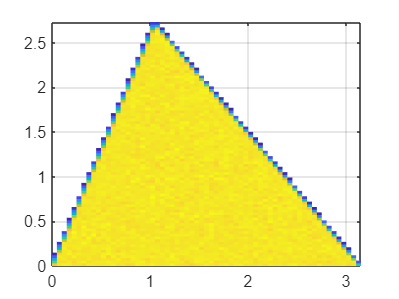

N=10^7;
Xs = rand(N,2);
Xmax = max(Xs,[],2);
Xmin = min(Xs,[],2);

x = pi*(Xmax - 2*Xmin/3);
y = exp(1)*(Xmin);

histogram2(x,y,DisplayStyle="tile")